# RACIPE anlaysis to find state frequency (number of mono, bi, tri etc parameter sets), phase frequency (overall as well as within each of the mono, bi, tri etc solutions, phase being the 2^4 = 16 possible solutions of the TTr)

clear all

% path to folder containing the RACIPE output
pt = "/Users/atchutasrinivasduddu/Library/CloudStorage" + ...
    "/OneDrive-IndianInstituteofScience/Duddu/2023/Spring 2023" + ...
    "/Toggle Tetrahedron/TTr/n_6_10/3/";
% reading the solution.dat file with all the solutions
solution_file = readtable(strcat(pt,'TTr_solution.dat'));
solution_file = table2array(solution_file);
% reading all the parameter sets
parameter_file = readtable(strcat(pt,'TTr_parameters.dat'));
prs_file = readtable(strcat(pt,'TTr.txt'));
% reading the VariableNames for parameter sets from prs file
parameter_file.Properties.VariableNames = ["S_no" "States_number" ...
    table2array(prs_file(:,1))'];

solution_file_Z = Z_normalizing(solution_file);
% ignoring multistable states of parameter sets giving more than 17 
% states simultaneously. 17 is arbitrary and it can be changed as 
% per wish provided the significant states (generally within 
% multistability 10 parameter sets)
solution_file_Z = solution_file_Z(solution_file_Z(:,2)<17,:);
% booleanizing the solutions with threshold considered 0 as can be 
% seen approximately from the ksdensity plots below for each node
bool_solution_file = phase_changer(solution_file_Z,[0 0 0 0]);
% state frequency calculation
state_frequency = state_count(bool_solution_file);
% struct with all phases for each of the multistability solution
[all_state_ia,all_state_phase_classification_in_phases_order, ... 
    all_state_phase_frequency,all_state_phases, ...
    only_phase_columns_of_solution_file] = phase_counter( ...
    bool_solution_file,(size(bool_solution_file,2)-3));
% dividing the solutions from the solution file according to its
% multistability for further phase frequency calculations
state_divided_bool_solution_files = state_divider(bool_solution_file);
% phase frequency calculations for all the multistability solution cases
[ia,phase_classification_in_phase_order,phase_frequency,all_phases, ...
    organized_bool_solution_file] =  ...
    phase_counting_and_arrangement_for_all_states( ...
    state_divided_bool_solution_files);

## Making ksdensity plots for each of the 4 nodes

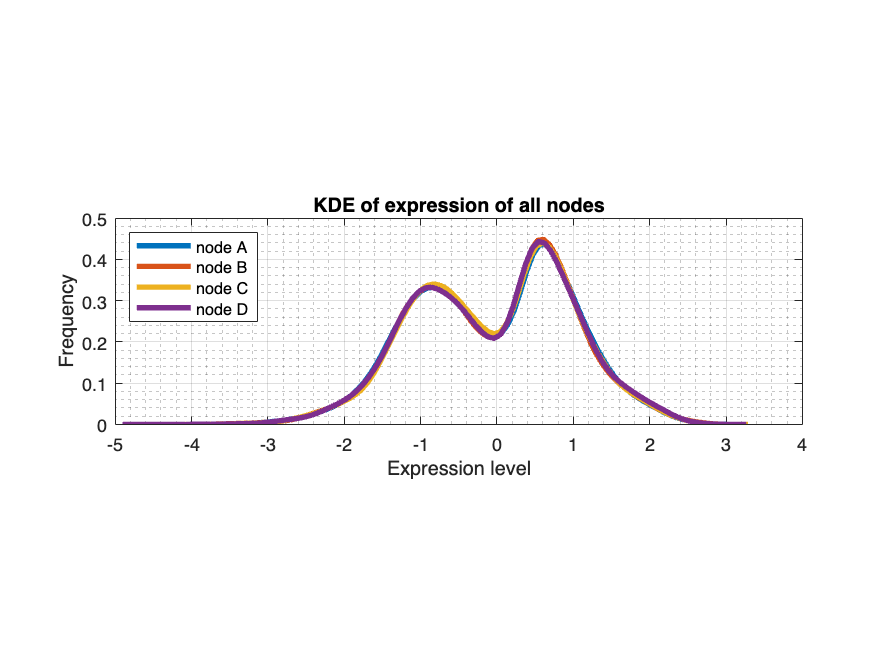

[f1,xi1] = ksdensity(solution_file_Z(:,4));
[f2,xi2] = ksdensity(solution_file_Z(:,5));
[f3,xi3] = ksdensity(solution_file_Z(:,6));
[f4,xi4] = ksdensity(solution_file_Z(:,7));
figure()
plot(xi1,f1,xi2,f2,xi3,f3,xi4,f4,'LineWidth',3);
grid on; grid(gca,'minor');
title('KDE of expression of all nodes');
xlabel('Expression level');
ylabel('Frequency');
pbaspect([10 3 1]);
legend('node A','node B','node C','node D','Location','northwest');

## Making bar plots for state frequency and phase frequency (for all  together as well as each multistability case separately)

% state frequency
state_freq(1) = figure();
bar(state_frequency);
grid on; grid(gca,'minor');
title('State frequency distribution');
xlabel('Number of solutions obtained from a parameter set');
ylabel('State Frequency');
pbaspect([1 1 1]);

% phase frequency all together
phase_freq(1) = figure();
bar(all_state_phases,all_state_phase_frequency/sum(all_state_phase_frequency));
grid on; grid(gca,'minor');
title('Phase frequency distribution over all parameter sets');
xlabel('Phase of the solution');
ylabel('Phase Frequency');
pbaspect([1 1 1]);

% phase frequency each multistable case separetely
field_names_by_state_division = fieldnames(all_phases);
for i = 1:length(fieldnames(all_phases))
    temp_phases = all_phases.(char(field_names_by_state_division(i)));
    temp_phase_frequency = phase_frequency.(char(...
        field_names_by_state_division(i)));
    % condition is so that all the very low frequency bars are avoinded in
    % the figure and xticklables of high frequent bars can be clearly seen
    temp_phase_frequency_conditional_index = logical(temp_phase_frequency>3);
    temp_phases = temp_phases(temp_phase_frequency_conditional_index);
    temp_phases = removecats(temp_phases);
    temp_phase_frequency = temp_phase_frequency(...
        temp_phase_frequency_conditional_index);
    phase_bar(i) = figure();
    phasebar(i) = bar(temp_phases,temp_phase_frequency/...
        sum(temp_phase_frequency));
    grid on; grid(gca,'minor');
    title(strcat("Phase frequency distribution for the solution with ",num2str(i)," states"));
    xlabel('Phase of the solution');
    ylabel('Phase Frequency');
    pbaspect([1 1 1]);
end

## Making heatmap considering only till hexastable solutions

(takes a lot of time with the clustering)

% solution_file_xx = readtable('TTr\n_6_10\3\TTr_solution.dat');
% solution_file_xx = table2array(solution_file_xx);
% % solution_file_xx = solution_file_xx(solution_file_xx(:,2)<6,:);
% % h = clustergram(solution_file_xx(:,4:end));
% [coeff,score,latent] = pca(solution_file_xx(1:5000,4:end));
% scatter3(score(:,1),score(:,2),score(:,3),2,'filled');
% % mapcaplot(solution_file_xx(1:2000,4:end));

## Functions used in the script

function solution_file_here = Z_normalizing(solution_file_here)
means = mean(solution_file_here(:,4:end));
stds = std(solution_file_here(:,4:end));
solution_file_here(:,4:end) = (solution_file_here(:,4:end)-means)./(stds);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The function above is to Z normalize the solutions.
% INPUT is the solution.dat file.
% OUTPUT is the same file with columns of expression values 
% Z-normalized.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function states_frequency = state_count(solution_file_here)
[C,ia,ic] = unique(solution_file_here(:,1:2),'rows');
counts_n = accumarray(ic,1);
states_frequency = accumarray(counts_n,1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The function above is to calculate the state frequencies i.e. the 
% distribution of the number of monostable states, bistable states
% and so on.
% INPUT is the solution.dat file (edited or unedited expression 
% values do not matter since we only require the first 2 columns 
% for this purpose).
% OUTPUT is the frequency vector in the increasing order of the 
% states in terms of mono, bi, tri etc.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function solution_file_here = phase_changer(solution_file_here,...
    threshold_values)
for i = 4:size(solution_file_here,2) 
    % 4 because first 3 coloumns are not relavent 
    % (see RACIPE output file structure)
    solution_file_here(:,i) = solution_file_here(:,i)>...
        threshold_values(1,i-3);
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The function above is to change the expression values in the 
% solution file to boolean 1s and 0s based on the threshold values 
% decided/estimated.
% INPUT is the Z-normalized solution.dat file and threshold values
% corresponding to each of the nodes.
% OUTPUT is the same solution.dat file with booleanized 
% exporession value columns.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function state_divided_bool_solution_files = state_divider(solution_file_here)
for i = 1:max(solution_file_here(:,2))
    state_solution_row_numbers = solution_file_here(:,2)==i;
    solution_rows = solution_file_here(state_solution_row_numbers,:);
    solution_rows = sortrows(solution_rows,[1 4:size(solution_rows,2)]);
    state_solution_field_name = strcat("solution_",num2str(i));
    state_divided_bool_solution_files.(state_solution_field_name)...
        = solution_rows;
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The function above is to categorize the booleanized solution 
% file according to the multistability.
% INPUT is the booleanized solution file.
% OUTPUT is a struct with each field corresponding to each 
% multistability case and them having the same boolean solutions.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function [ia,phase_classification_in_phase_order,...
    phase_frequency,all_phases,organized_bool_solution_file] ...
    = phase_counting_and_arrangement_for_all_states(...
    state_divided_bool_solution_files)
state_solution_fieldnames = fieldnames(state_divided_bool_solution_files);
for i = 1:length(state_solution_fieldnames)
    to_be_modified_bool_solution_file = ...
        state_divided_bool_solution_files.(state_solution_fieldnames{i});
    temp_bool_solution_file = zeros((size(...
        to_be_modified_bool_solution_file,1)/i),(i*size(...
        to_be_modified_bool_solution_file,2)));
    for j = 0:(i-1)
        temp_bool_solution_file_store = ...
            to_be_modified_bool_solution_file((j+1):i:end,:);
        temp_bool_solution_file(:,(j*size(...
            to_be_modified_bool_solution_file,2))+1:((j+1)*...
            size(to_be_modified_bool_solution_file,2))) = ...
            temp_bool_solution_file_store;
    end
    [temp_ia,temp_phase_classification_in_phase_order,...
        temp_phase_frequency,temp_all_phases] = phase_counter(...
        temp_bool_solution_file,((size(temp_bool_solution_file,2)/i)-3));
    all_phases.(strcat("solution_",num2str(i))) = temp_all_phases;
    ia.(strcat("solution_",num2str(i))) = temp_ia;
    phase_classification_in_phase_order.(strcat("solution_",num2str(i)))...
        = temp_phase_classification_in_phase_order;
    phase_frequency.(strcat("solution_",num2str(i))) = temp_phase_frequency;
    organized_bool_solution_file.(strcat("solution_",num2str(i)))...
        = temp_bool_solution_file;
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The function above is to calculate the phase frequencies of each of the
% state divided boooleanized solution files with their corresponding phases 
% found out wiht the next function. 
% INPUT is each of the state divided booleanized solution file.
% OUTPUT is a struct with each field corresponding to each 
% multistability case and the phase frequencies present in them.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function [ia,ic,phase_frequency,all_phases,...
    only_phase_columns_of_solution_file] = phase_counter(...
    solution_file_here,number_of_states)
total_columns_of_solution_file = 1:size(solution_file_here,2);
% some phases might not even occur so further processing is required
only_phase_columns_of_solution_file = logical(mod(...
    total_columns_of_solution_file,3+number_of_states)~=1 & ...
    mod(total_columns_of_solution_file,3+number_of_states)~=2 & ...
    mod(total_columns_of_solution_file,3+number_of_states)~=3);
[C,ia,ic] = unique(solution_file_here(:,...
    only_phase_columns_of_solution_file),'rows');
frequency = accumarray(ic,1); 
phase_frequency = frequency;
C = categorical(cellstr(char(string(C).join(''))));
all_phases = C;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The function above is to categorize the phases of the booleanized 
% solution file according to the multistability.
% INPUT is each of the state divided booleanized solution file and value 
% of the corresponding multistability.
% OUTPUT is a struct with each field corresponding to each 
% multistability case and the phases present in them.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

